Pagrindinė užduotis

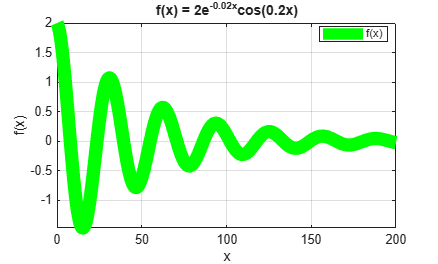

x = linspace(0, 200, 300);
f = 2 * exp(-0.02*x) .* cos(0.2*x);
figure();
plot(x, f, 'g', 'LineWidth', 10);

title('f(x) = 2e^{-0.02x}cos(0.2x)');
xlabel('x');
ylabel('f(x)');
axis([min(x) max(x) min(f) max(f)]);
legend('f(x)', 'Location', 'best');
grid on;

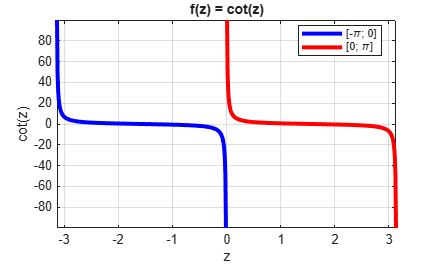

z1 = linspace(-pi + 0.01, -0.01, 300);
z2 = linspace(0.01, pi - 0.01, 300);

f1 = cot(z1);
f2 = cot(z2);

figure();
plot(z1, f1, 'b', 'LineWidth', 3);
hold on;
plot(z2, f2, 'r', 'LineWidth', 3);
hold off;
grid on;

title('f(z) = cot(z)');
xlabel('z');
ylabel('cot(z)');
axis([min(z1) max(z2) min([f1 f2]) max([f1 f2])]);
legend('[-\pi; 0]', '[0; \pi]', 'Location', 'best');
grid on;

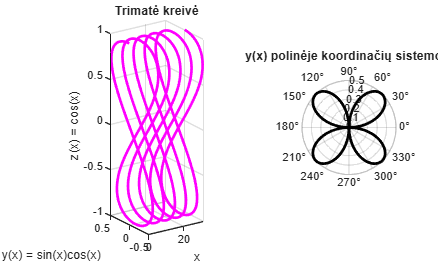

x = linspace(0, 10*pi, 500);
y = sin(x) .* cos(x);
z = cos(x);

figure();

subplot(1,2,1);

plot3(x, y, z, 'm', 'LineWidth', 2);
grid on;

title('Trimatė kreivė');
xlabel('x');
ylabel('y(x) = sin(x)cos(x)');
zlabel('z(x) = cos(x)');

subplot(1,2,2);
polarplot(x, y, 'k', 'LineWidth', 2);
title('y(x) polinėje koordinačių sistemoje');

Papildoma užduotis

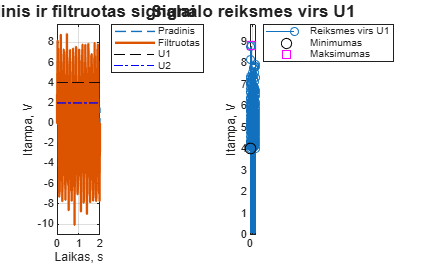

clear; clc; close all;

% Signalas
t = 0:0.002:2;
A = 6;
f = 7;
sigma = 1.2;
U1 = 4;
U2 = 2;

s = A*sin(2*pi*f*t) + sigma*randn(size(t));

filtruotas = s;
filtruotas(abs(s) < U2) = 0;

% Pirmas grafikas
figure;
subplot(1,2,1);

plot(t, s, '--', 'LineWidth', 1);
hold on;
plot(t, filtruotas, '-', 'LineWidth', 1.75);
plot([t(1) t(end)], [U1 U1], 'k--');
plot([t(1) t(end)], [U2 U2], 'b-.');

title('Pradinis ir filtruotas signalai', ...
      'FontWeight', 'bold', 'FontSize', 13);
xlabel('Laikas, s');
ylabel('Itampa, V');
legend('Pradinis', 'Filtruotas', 'U1', 'U2', ...
       'Location', 'bestoutside');
axis([0 2 min(s)-1 max([s U1 U2])+1]);
grid on;
hold off;

% Atrenkame reiksmes ir ju laikus
i = s > U1;
u = s(i);
tt = t(i);

% Antras grafikas
subplot(1,2,2);

stem(tt, u);
hold on;
plot(tt(u == min(u)), u(u == min(u)), 'ko', 'MarkerSize', 8);
plot(tt(u == max(u)), u(u == max(u)), 'ms', 'MarkerSize', 8);

title('Signalo reiksmes virs U1', ...
      'FontWeight', 'bold', 'FontSize', 13);
xlabel('Laikas, s');
ylabel('Itampa, V');
legend('Reiksmes virs U1', 'Minimumas', 'Maksimumas', ...
       'Location', 'bestoutside');
axis([0 2 0 max(u)+1]);
grid on;
hold off;